# Data exploration for raw xy files

## PURPOSE

This is code is to calculate general metrics for the xy output from antrax that were merged

## INPUT

% input file information
xyDir = "/Users/lizimai/Insync/zimai.li@evobio.eu/Google Drive/DoctorToBe/01_Projects/ZIM01_Nematode/P2_Tracking/01_Data/cam5";
% xyDir = "/Users/zli/Insync/zimai.li@evobio.eu/Google Drive/DoctorToBe/01_Projects/ZIM01_Nematode/P2_Tracking/01_Data/cam5";
xyFileinfo = dir(fullfile(xyDir,'xy*.mat'));
xyFilename = (sort({xyFileinfo.name}))';

% create output matrix with experiment information in the xy file names
output = table(xyFilename,'VariableNames',{'Filename'});
splitNames = split(output.Filename, ["_","."]);
output.Treatment = splitNames(:, 2);
output.Number = str2double(splitNames(:, 3));

% data filtering
maxNumAnts = 8; % maximum number of ants in one colony
treatRm = "X"; % treatment to remove
frameKeep = 864000; % frame to keep

% ant information
antColour = ["BB","BG","BR","GG","GR","RB","RG","GG"]'; % colour code: sequence has to be matched with column sequence in the xy matrix
antTable = table(antColour, 'VariableNames',{'Colour'}); % create empty ant table for data storage of ants in each colony 

% run find nest code
inNestWithNansRaw = copyNans(xy, inNest);
inNestWithNans = inNestWithNansRaw(:,1);

## Clean Data

% filter some treatments
outputFiltered = output(output.Treatment~=treatRm,:);
numFile = length(outputFiltered.Filename);

% merge segments of inNestWithNansRaw
for i = 1:size(inNestWithNansRaw,1)
    for j = 2:size(inNestWithNansRaw,2)
    inNestWithNans{i} = [inNestWithNans{i};inNestWithNansRaw{i,j}];
    end
end

## Plot the trajectory of each ant in every colony

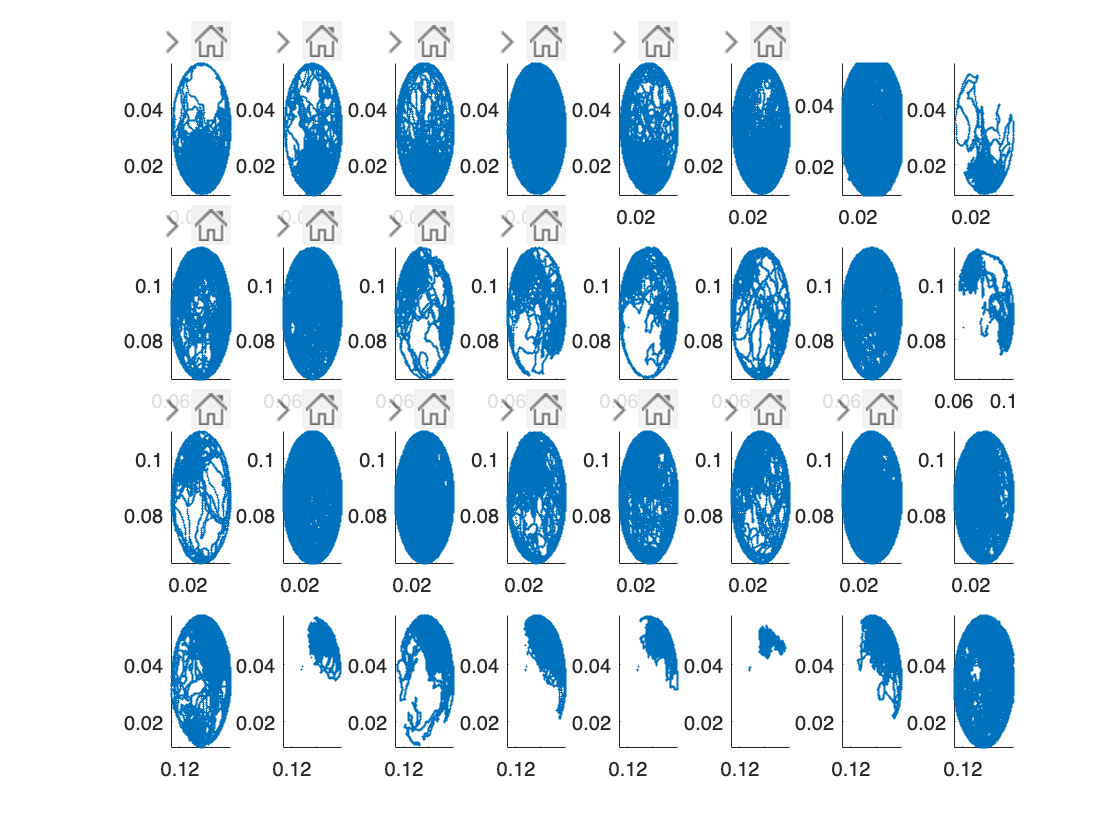

figure;
for i = 1:numFile
     xyMatrix = load(fullfile(xyDir, outputFiltered.Filename(i))).xy(1:frameKeep,:); % load xy matrix
     numAnts = size(xyMatrix, 2)/2; % number of ants equals to number of columns
     xlim_min = min(min(xyMatrix(:,1:2:2*numAnts-1))); % set x and y axis lim
     xlim_max = max(max(xyMatrix(:,1:2:2*numAnts-1)));
     ylim_min = min(min(xyMatrix(:,2:2:2*numAnts)));
     ylim_max = max(max(xyMatrix(:,2:2:2*numAnts)));
     for j = 1:numAnts
        subplot(numFile,maxNumAnts, (i-1)*maxNumAnts+j); % make numFile*maxNumAnts grid plot
        axis ij;
        x= xyMatrix(:,2*j-1);
        y = xyMatrix(:,2*j);
        % assignment rate
        scatter(x, y, 0.5, 'filled');
        xlim([xlim_min,xlim_max]);
        ylim([ylim_min,ylim_max]);
     end
end

## Calculate Metrics for Ants and Colonies

**ATTENTION: **Run FindNest Before this section

for i = 1:numFile
    xyMatrix = load(fullfile(xyDir, outputFiltered.Filename(i))).xy(1:frameKeep,:); % load xy matrix
    numAnts = size(xyMatrix, 2)/2; % number of ants equals to number of columns
    
    %% calculate basic statistics for ants
    for j = 1:length(antColour)
        antXy = xyMatrix(:,[j*2-1, j*2]);
        assignmentRate = 1 - sum(isnan(antXy),'all')/(size(xyMatrix, 1)*2);
        antTable.AssignmentRate(j) = assignmentRate;
        antTable.InNestRatio(j) = sum(inNestWithNans{i,1}(:,j),"omitnan")/length(inNestWithNans{i,1}(:,j));  
    end
    
    %% calculate basic statistics for colonies  
   outputFiltered.NumAnts(i) = numAnts; % count number of ants
   outputFiltered.AntOutput{i} = antTable ; % insert ant output
   outputFiltered.AssignmentRate(i) = mean(outputFiltered.AntOutput{i,1}.AssignmentRate); % count mean assignment rate
   outputFiltered.InNestRatioMean(i) = mean(outputFiltered.AntOutput{i,1}.InNestRatio); % count mean in-nest ratio
   outputFiltered.InNestRatioVariance(i) = var(outputFiltered.AntOutput{i,1}.InNestRatio); % count mean in-nest ratio
   outputFiltered.InNestRatioGlobal(i) = sum(inNestWithNans{i,1}, "all", "omitnan")/(length(inNestWithNans{i,1})*numAnts);
end

outputFiltered

outputFiltered = 4×9 table
       Filename       Treatment    Number    NumAnts     AntOutput     AssignmentRate    InNestRatioMean    InNestRatioVariance    InNestRatioGlobal
    ______________    _________    ______    _______    ___________    ______________    _______________    ___________________    _________________

    {'xy_C_2.mat'}      {'C'}        2          8       {8×3 table}       0.75175             0.6836             0.0010358               0.6836     
    {'xy_C_9.mat'}      {'C'}        9          8       {8×3 table}       0.91095             0.8043            0.00038906               0.8043     
    {'xy_T_1.mat'}      {'T'}        1          8       {8×3 table}   